# サッカーのホームアドバンテージ

clear;
clc;
close all;

2010年代の各国リーグのホーム・アウェーそれぞれの総得点を読み込む

(データ元：https://www.worldfootball.net/)

load('../data/tbl_goals_world.mat');
summary(tbl_goals_world)

Variables:

    countryName: 961×1 categorical

        Values:

            Albania                               9   
            Algeria                               9   
            Andorra                               9   
            Argentina                             5   
            Argentina-Apertura                    2   
            Argentina-Clausura                    2   
            Argentina-Final                       2   
            Argentina-Inicial                     3   
            Armenia                               9   
            Australia                             9   
            Austria                               9   
            Azerbaijan                            9   
            Bahrain                               9   
            Belarus                              10   
            Belgium                               9   
            Belgium-Playoff-I                     9   
            Belgium-Playoff-IIA       

試合数の少ない(ここでは50試合以下の)リーグを除外する

tbl_goals_world(tbl_goals_world.matches<=50,:)=[];
tbl_confederations=readtable('../data/countryNameAndConfederation.xlsx');
tbl_confederations.Confederation=categorical(tbl_confederations.Confederation);
confederationCats=unique(tbl_confederations.Confederation);

markerTypeStrs='osd^v>'

markerTypeStrs = 'osd^v>'

for n1=1:size(confederationCats,1)
    tmpConfName=confederationCats(n1)
    tmpCountryNames= ...
        tbl_confederations.CountryName(tbl_confederations.Confederation==tmpConfName);
    ind= ismember(tbl_goals_world.countryName, tmpCountryNames);
    gf=tbl_goals_world.homeGoals(ind,:);
    ga=tbl_goals_world.awayGoals(ind,:);
    pWin=tbl_goals_world.homeWins(ind,:) ...
        ./tbl_goals_world.matches(ind,:);
    pLose=tbl_goals_world.homeLoses(ind,:) ...
        ./tbl_goals_world.matches(ind,:);
    matchNums=tbl_goals_world.matches(ind,:);

    figure(1)
    hndl(n1)=scatter(gf./ga, pWin-pLose, ...
        markerTypeStrs(n1),'MarkerFaceAlpha',0.2, ...
        'MarkerFaceColor','flat', ...
        'markerEdgeAlpha',1);

    grid on;
    hold on
    set(gca,'FontName','メイリオ','FontSize',12)
    xlabel('(ホーム得点)/(アウェー得点)')
    ylabel('(ホーム勝率)-(アウェー勝率)')

end

tmpConfName = categorical
     AFC 


tmpConfName = categorical
     CAF 


tmpConfName = categorical
     CONCACAF 


tmpConfName = categorical
     CONMEBOL 


tmpConfName = categorical
     OFC 


tmpConfName = categorical
     UEFA 


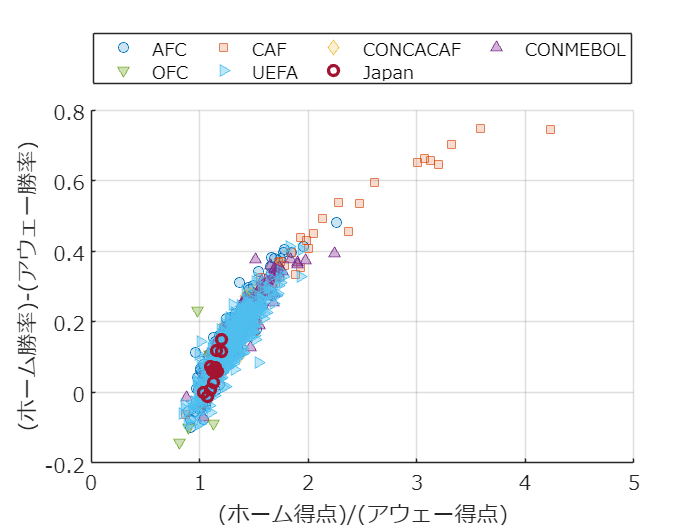


ind= find((tbl_goals_world.countryName=='Japan') + ...
    (tbl_goals_world.countryName=='Japan-1st') + ...
    (tbl_goals_world.countryName=='Japan-2nd'));

matchNums_JP=tbl_goals_world.matches((ind));
gf_JP=tbl_goals_world.homeGoals(ind,:);
ga_JP=tbl_goals_world.awayGoals(ind,:);
pWin_JP=tbl_goals_world.homeWins(ind,:) ...
    ./tbl_goals_world.matches(ind,:);
pLose_JP=tbl_goals_world.homeLoses(ind,:) ...
    ./tbl_goals_world.matches(ind,:);

hndl(size(confederationCats,1)+1)=scatter(gf_JP./ga_JP, ...
    pWin_JP-pLose_JP, ...
    markerTypeStrs(1), 'linewidth',2,       'markerEdgeAlpha',1);

legend(hndl,[categories( confederationCats);{'Japan'}], ...
    'Location','northoutside','Orientation','horizontal', ...
    'NumColumns',4);
exportgraphics(gcf,'fig_homeAdv-WinProbDiff.pdf');

saveas(gcf,'fig_homeAdv-WinProbDiff.fig');